function [C_L, C_D] = supersonicShockwave(AoA, Ma, Tau)
    C_L = supersonicShockwaveLift(AoA, Ma);
    C_D = supersonicShockwaveDrag(AoA, Ma, Tau);
end

# Shock Wave Lift and Drag - Basic Theory

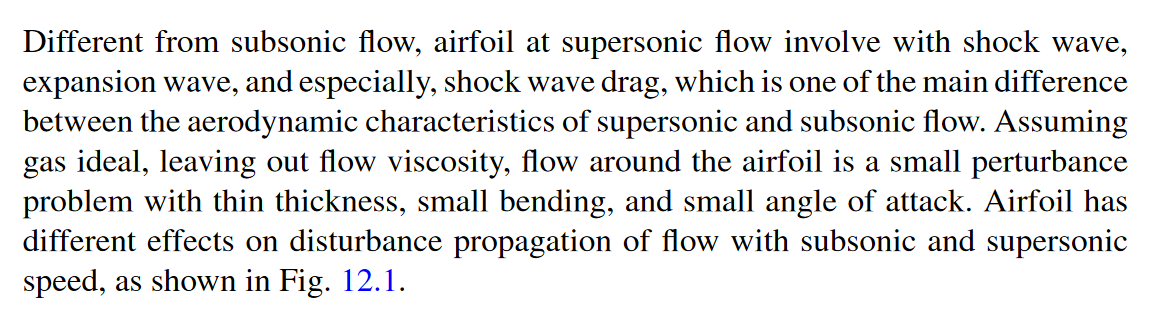

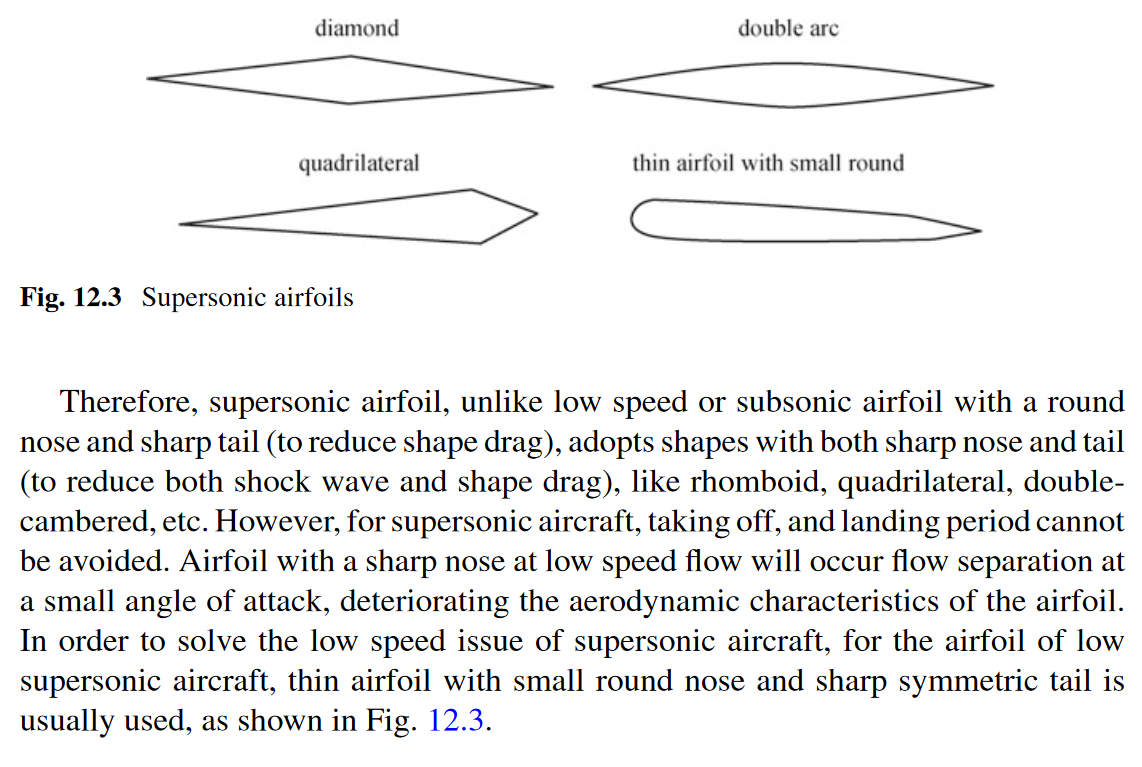

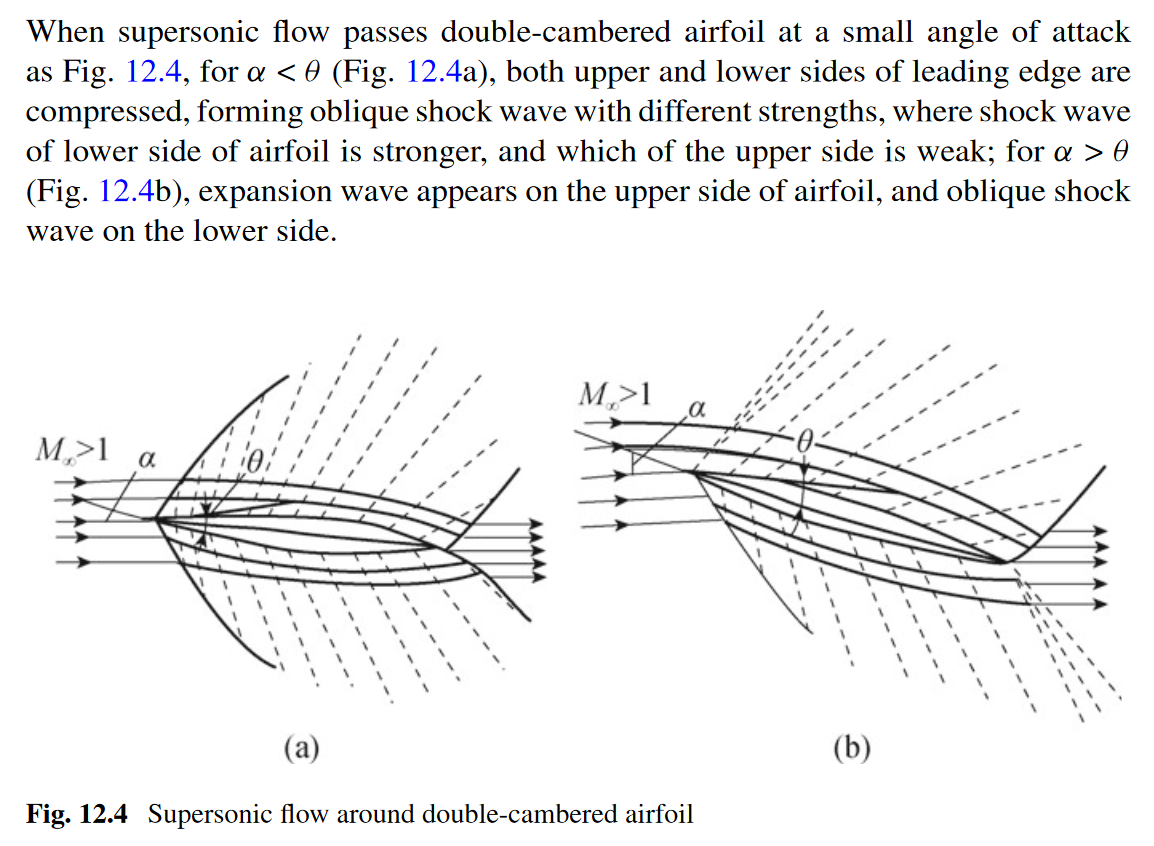

[P. Liu, Aerodynamics, [https://doi.org/10.1007/978-981-19-4586-1_12]](https://doi.org/10.1007/978-981-19-4586-1_12])

# **Shock Wave Lift - Linearized Theory of Thin Airfoil at Supersonic Flow**

## Basics of pressure difference:

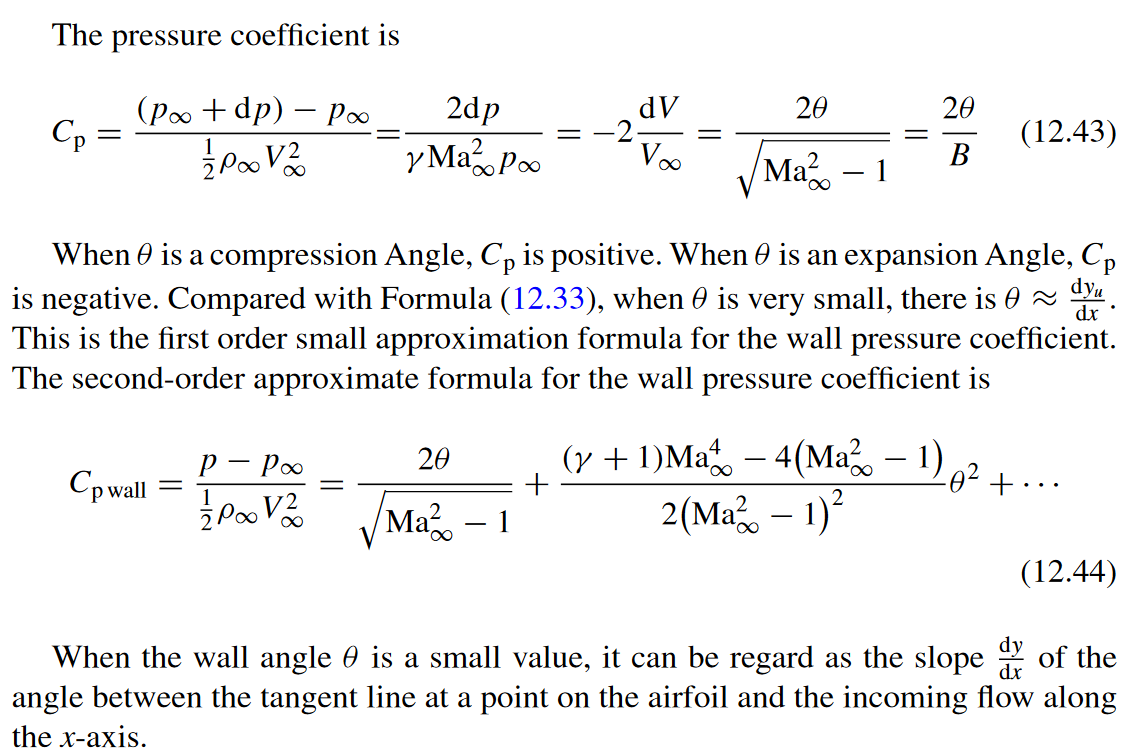

[P. Liu, Aerodynamics, [https://doi.org/10.1007/978-981-19-4586-1_12]](https://doi.org/10.1007/978-981-19-4586-1_12])

## Therefore Lift Coefficient:

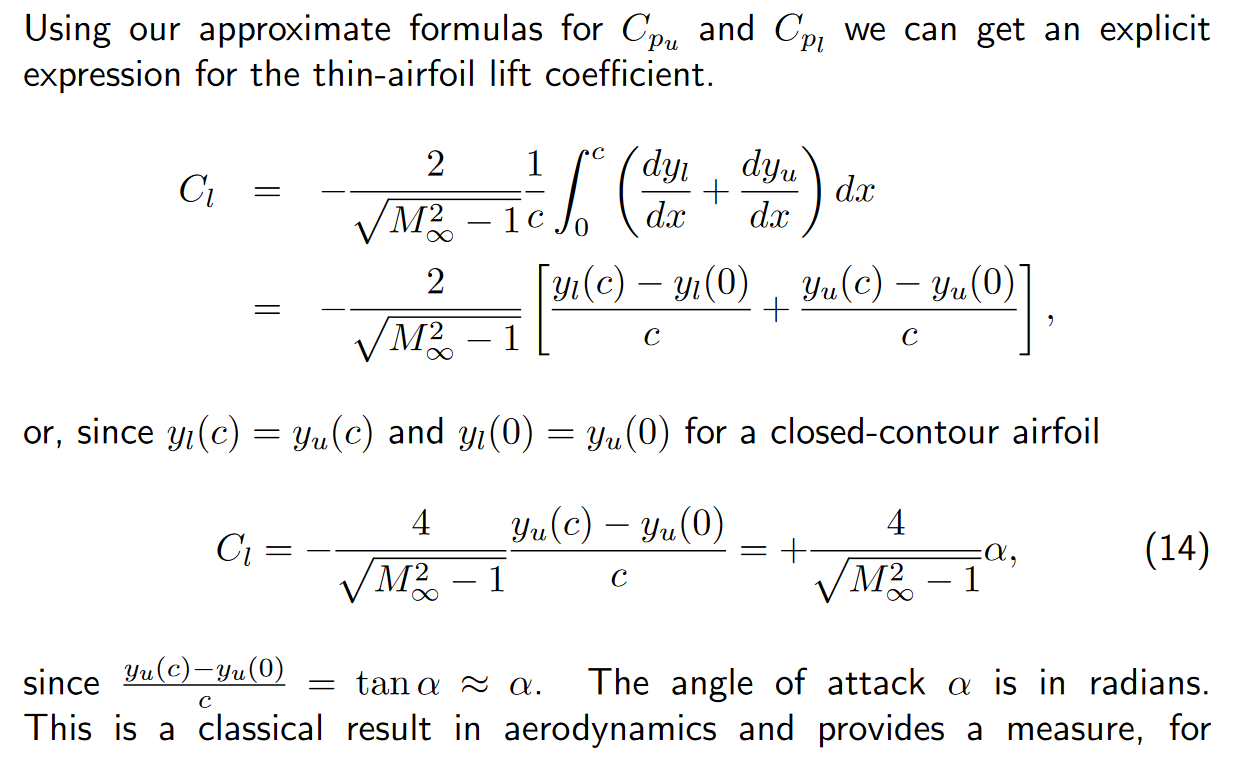

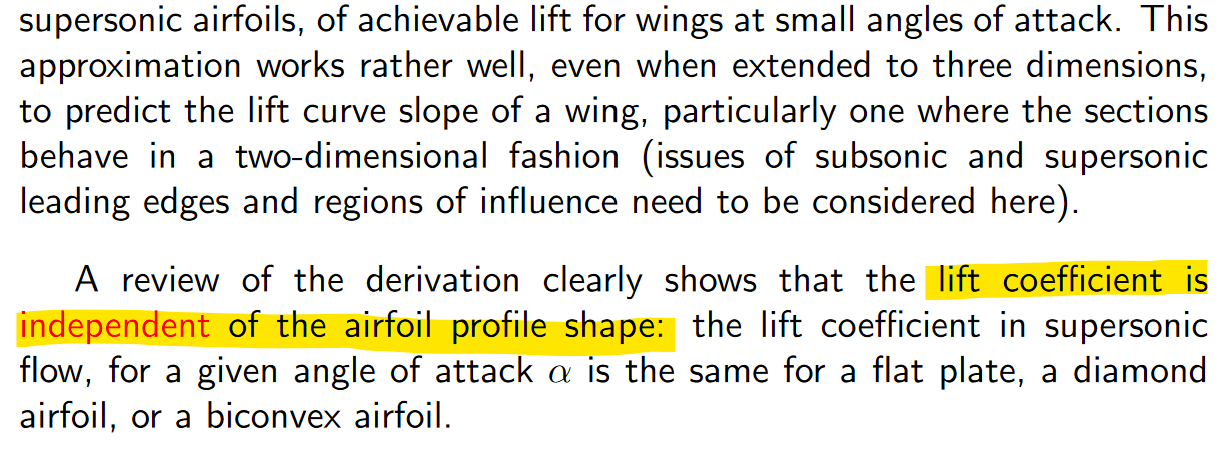

[http://aero-comlab.stanford.edu/aa200b/lect_notes/lect5.pdf]

Alings with P. Liu:

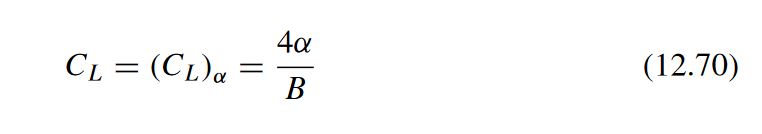

Note:

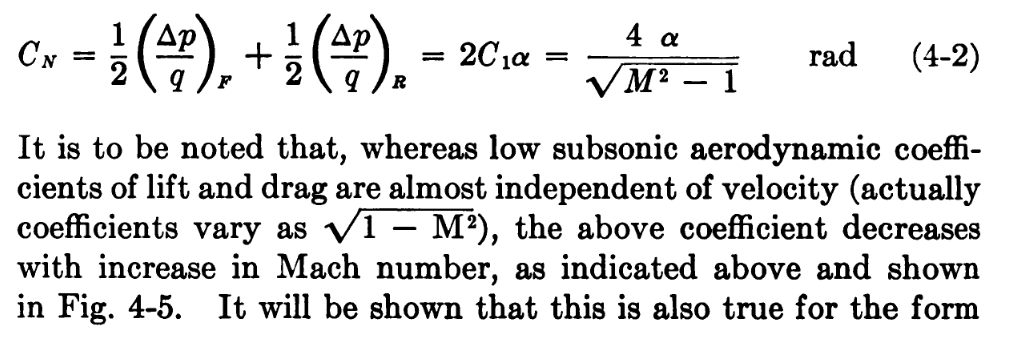

[E. Arthur Bonney - Engineering Supersonic Aerodynamics]

## And Lift Force:

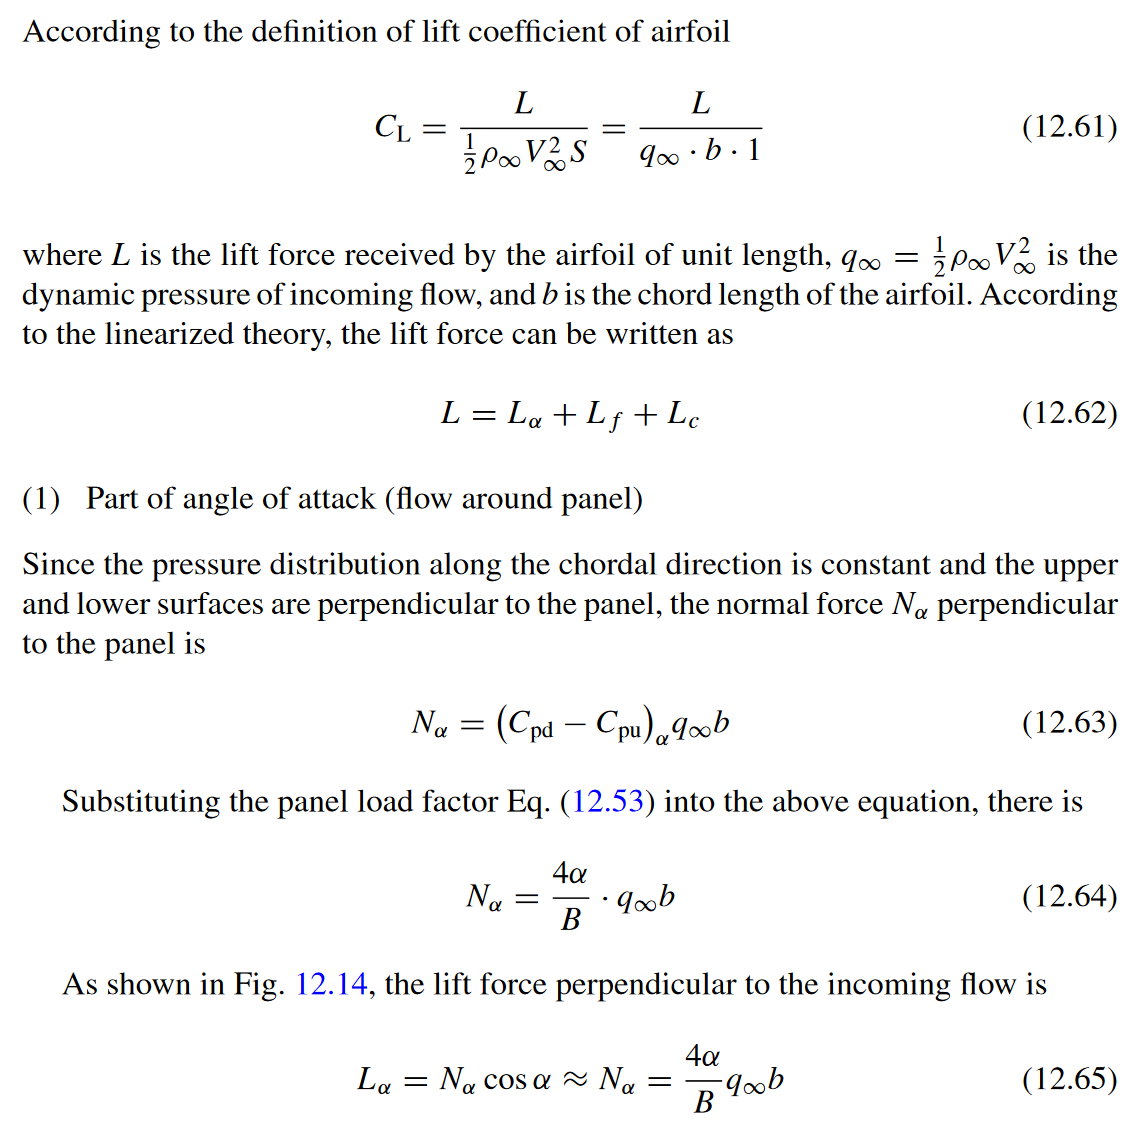

We don't have camber and neglegable thinckness, also:

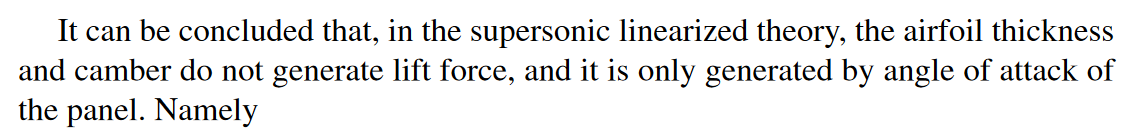

[P. Liu, Aerodynamics, [https://doi.org/10.1007/978-981-19-4586-1_12]](https://doi.org/10.1007/978-981-19-4586-1_12])    

function C_L = supersonicShockwaveLift(AoA, Ma)
%Lift Coefficient due to supersonic shock wave for any thin fin profile:
fprintf("supersonicShockwaveLift() assumes: \n\t - attached supersonic flow (low AoA, Ma) \n\t - thin flat plate airfoil \n\t - no impact of sweep angle \n");

    if AoA > 7
        warndlg("Warning: Angle of Attack (AoA) is more than 7°, Linear Lift Theory assumes attached flow and low AoA", "supersonicShockwaveLift()");
    end

    if Ma > 2
        warndlg("Warning: Mach Number (Ma) is above 2, Linear Lift Theory assumes supersonic attached flow. (for hypersonic flow use 'Newtonian Impact Theory')", "supersonicShockwaveLift()");
    end
    C_L = 4*(AoA*pi/180)/sqrt(Ma^2-1);
end


# **Supersonic Drag - General Theory**

## 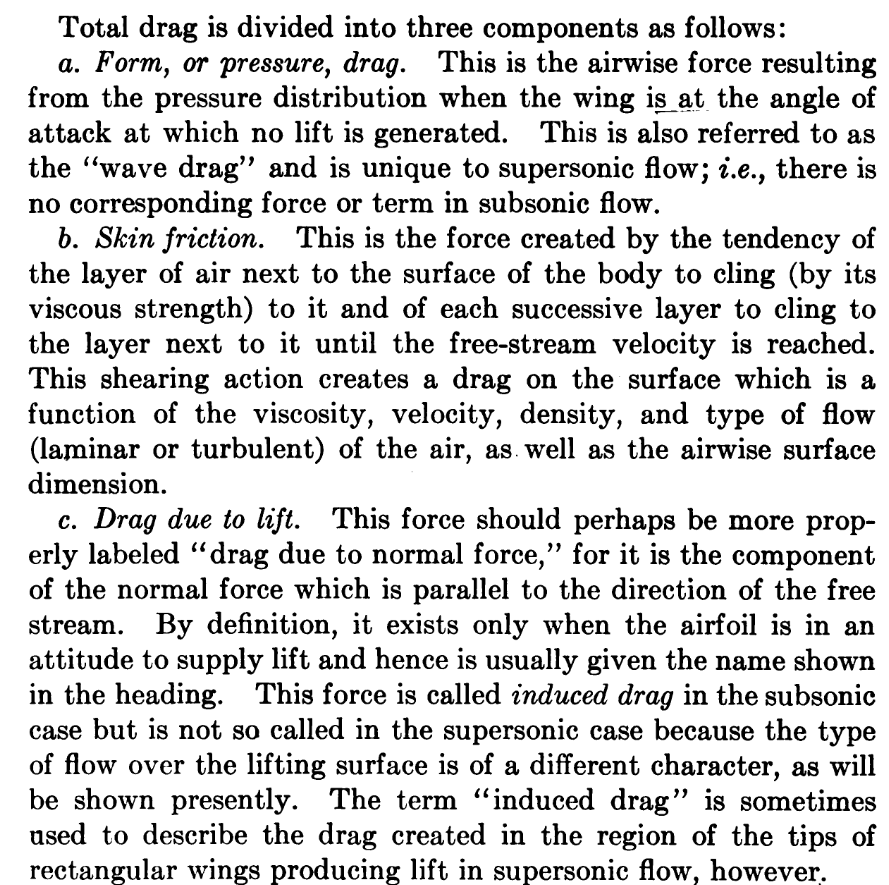

[E. Arthur Bonney - Engineering Supersonic Aerodynamics P. 112]

## Therefore Shock Wave Drag:

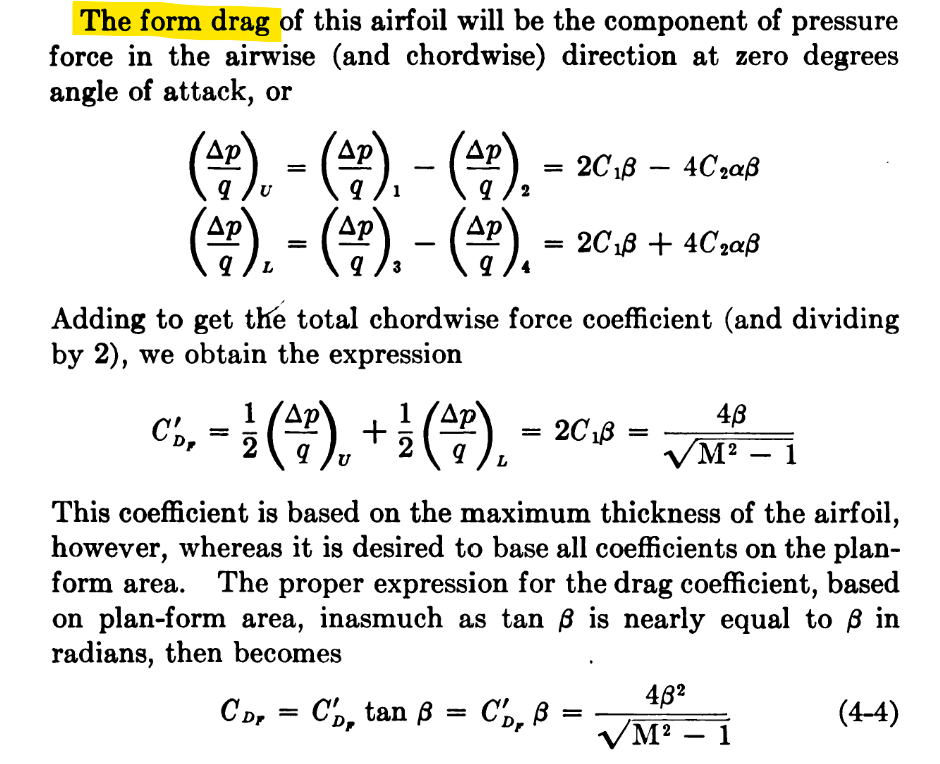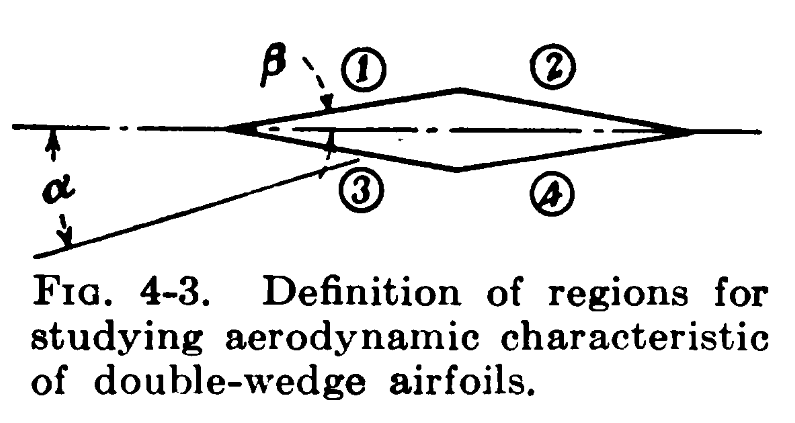

[E. Arthur Bonney - Engineering Supersonic Aerodynamics P. 116]

function C_Dw = supersonicShockwaveDrag(Ma, Tau)
%Drag Coefficient due to supersonic shock wave for any thin fin profile:
% Tau ... diamond airfoil half angle "τ" aka. "Beta"
    Tau_rad = Tau*pi/180;
    C_Dw=4*Tau_rad^2/sqrt(Ma^2-1);
end

- *C: Skin Friction and Drag-due-to-Lift in seperate fucntion, as this script just aims to cover the shock phenomonon*

## Comment on Stanford Source on Drag:

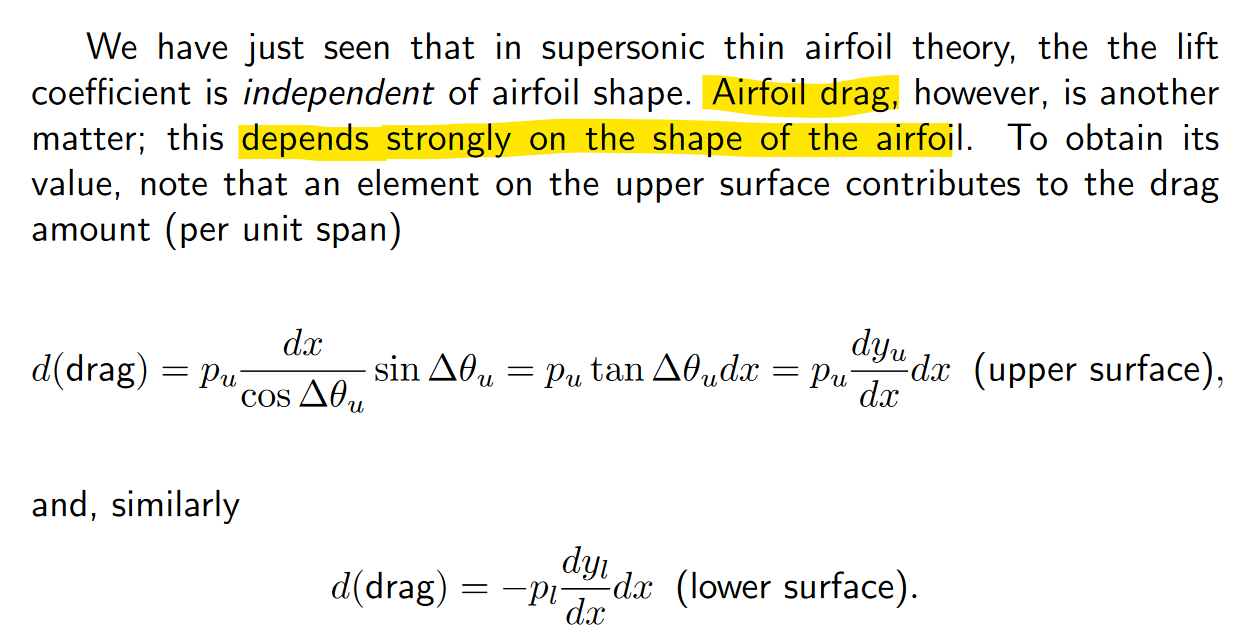

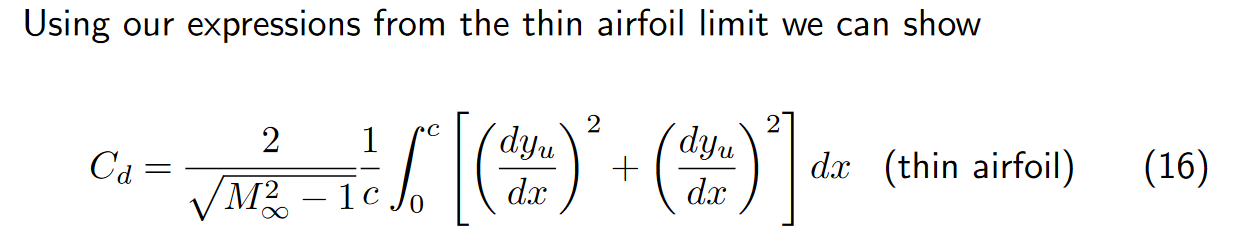

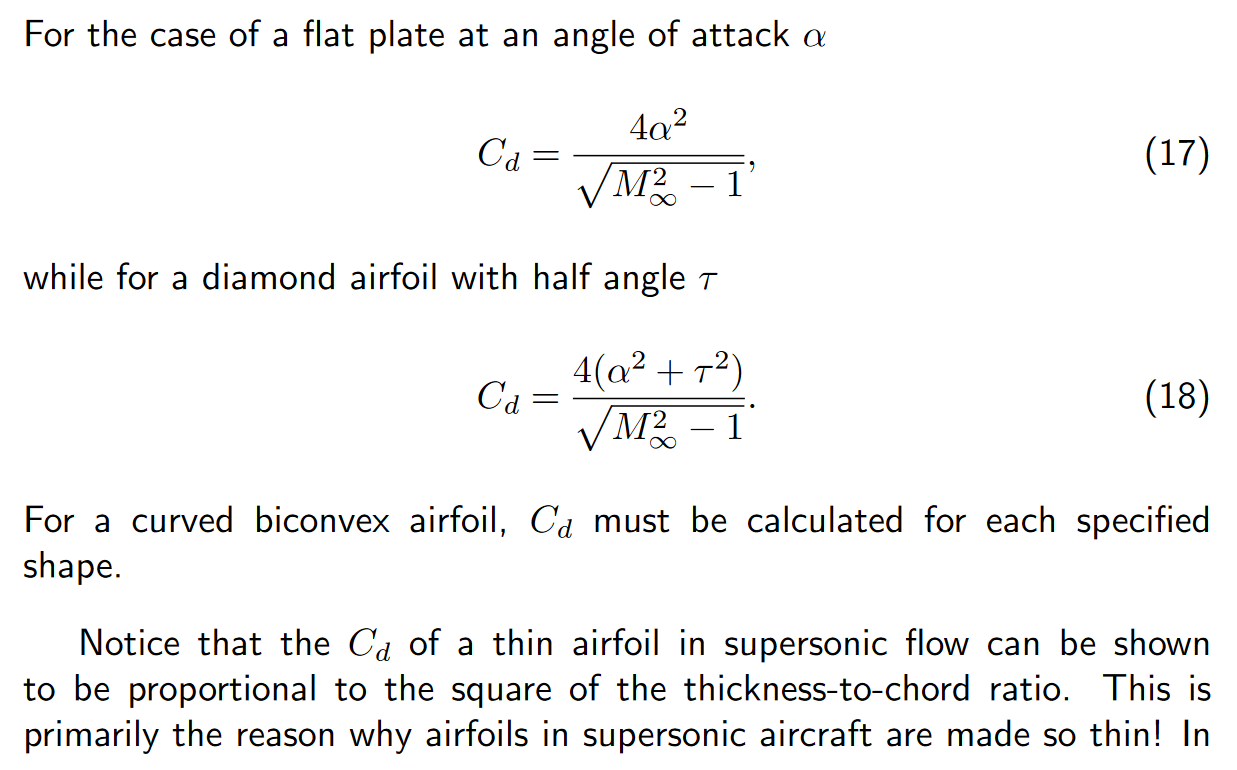

[http://aero-comlab.stanford.edu/aa200b/lect_notes/lect5.pdf]

- *C: Formula (17) is just the ****drag-due-to-lift****, as therer is theoretically no ****shock wave drag**** with an infinitly thin plate at zero angle*

- *C: In Formula (18) they added up the ****shock wave drag ****and ****drag-due-to-lift**** (ref. to first screenshot in "***Supersonic Drag - General Theory")**

## Comment on P. Liu Source on Drag:

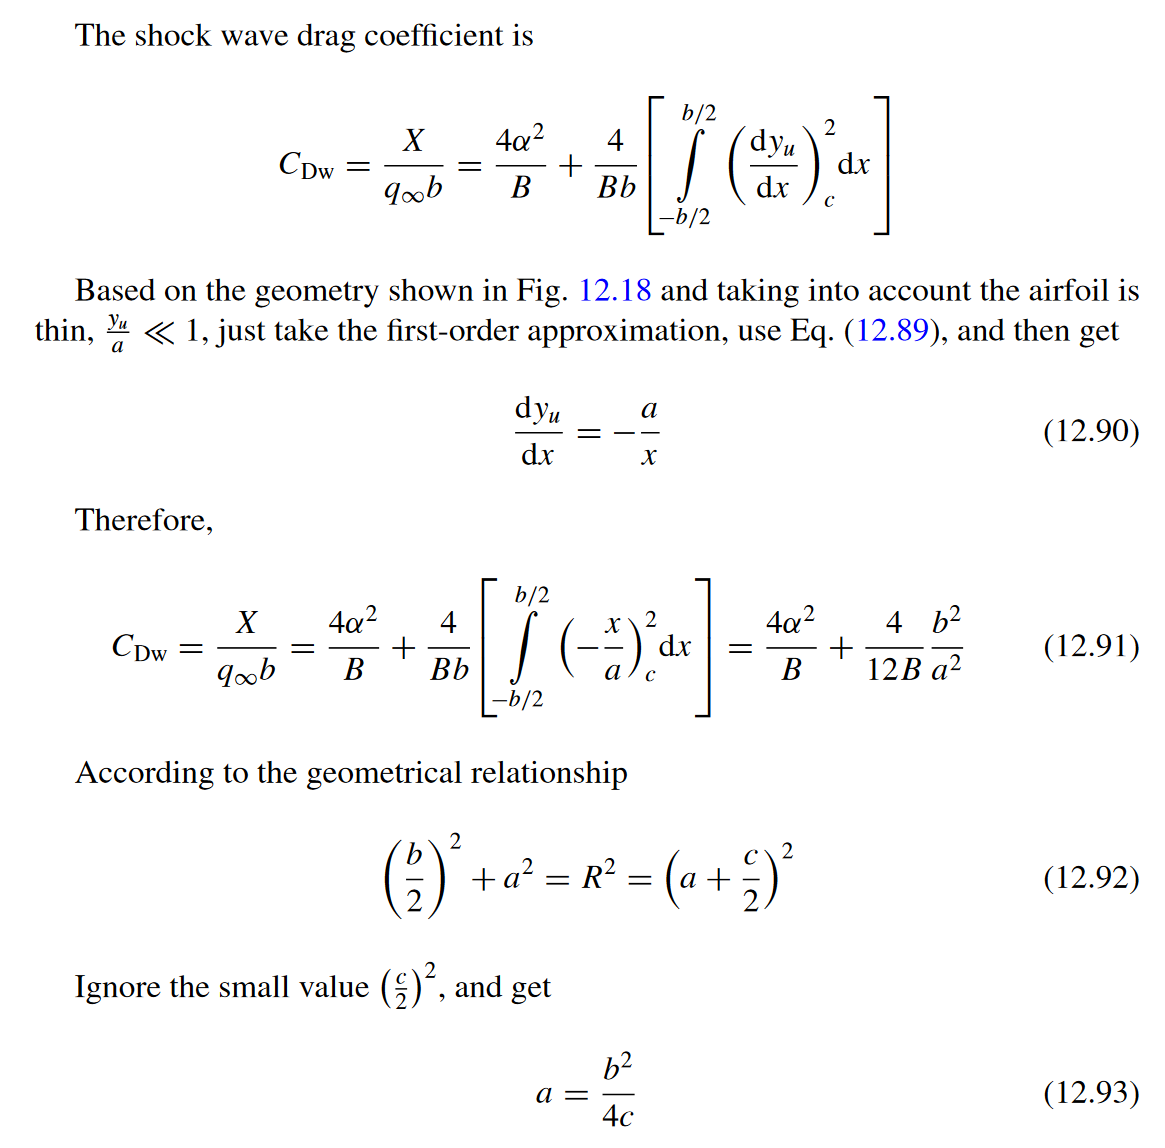

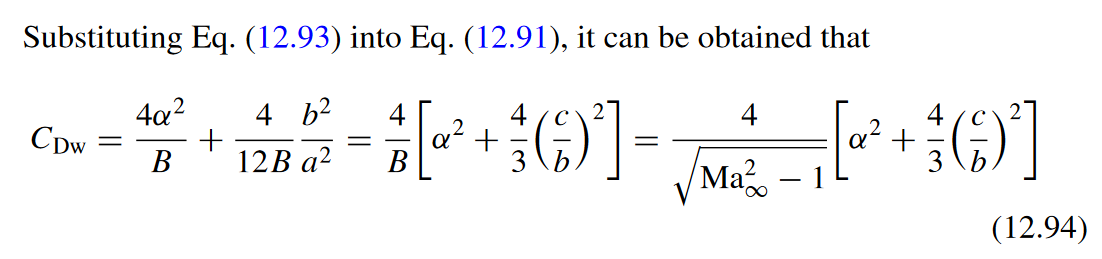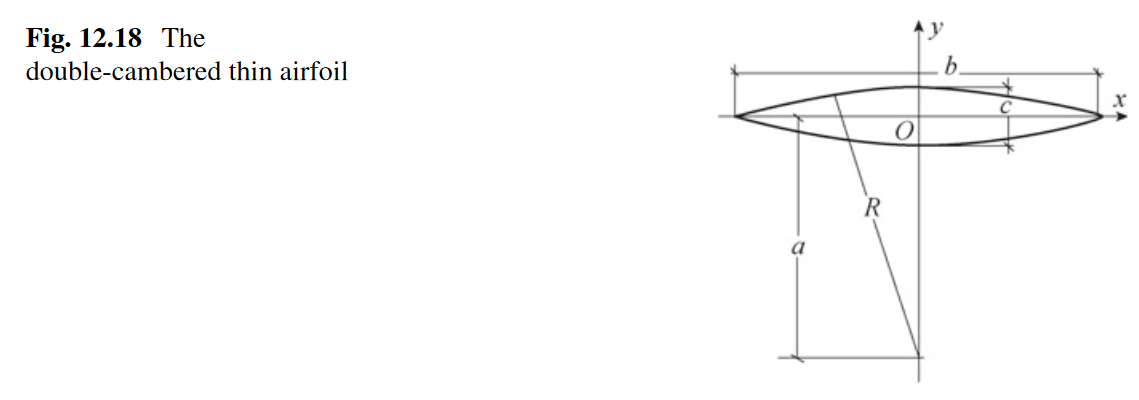

[P. Liu, Aerodynamics, [https://doi.org/10.1007/978-981-19-4586-1_12]](https://doi.org/10.1007/978-981-19-4586-1_12])

- *C: In Formula (12.91) with the first term 4*alpha^2/B the ****drag-due-to-lift ****is considered in the whole "shock wave drag coefficient" Formula of C_Dw (12.94)*

- *C: This source consideres a double-cambered thin airfoil and (not a double wedge aka symmetric diamond shape as Stanford and E. Arthur Bonney) thus the 4/3*(c/b)^2*

# Experimental Approval

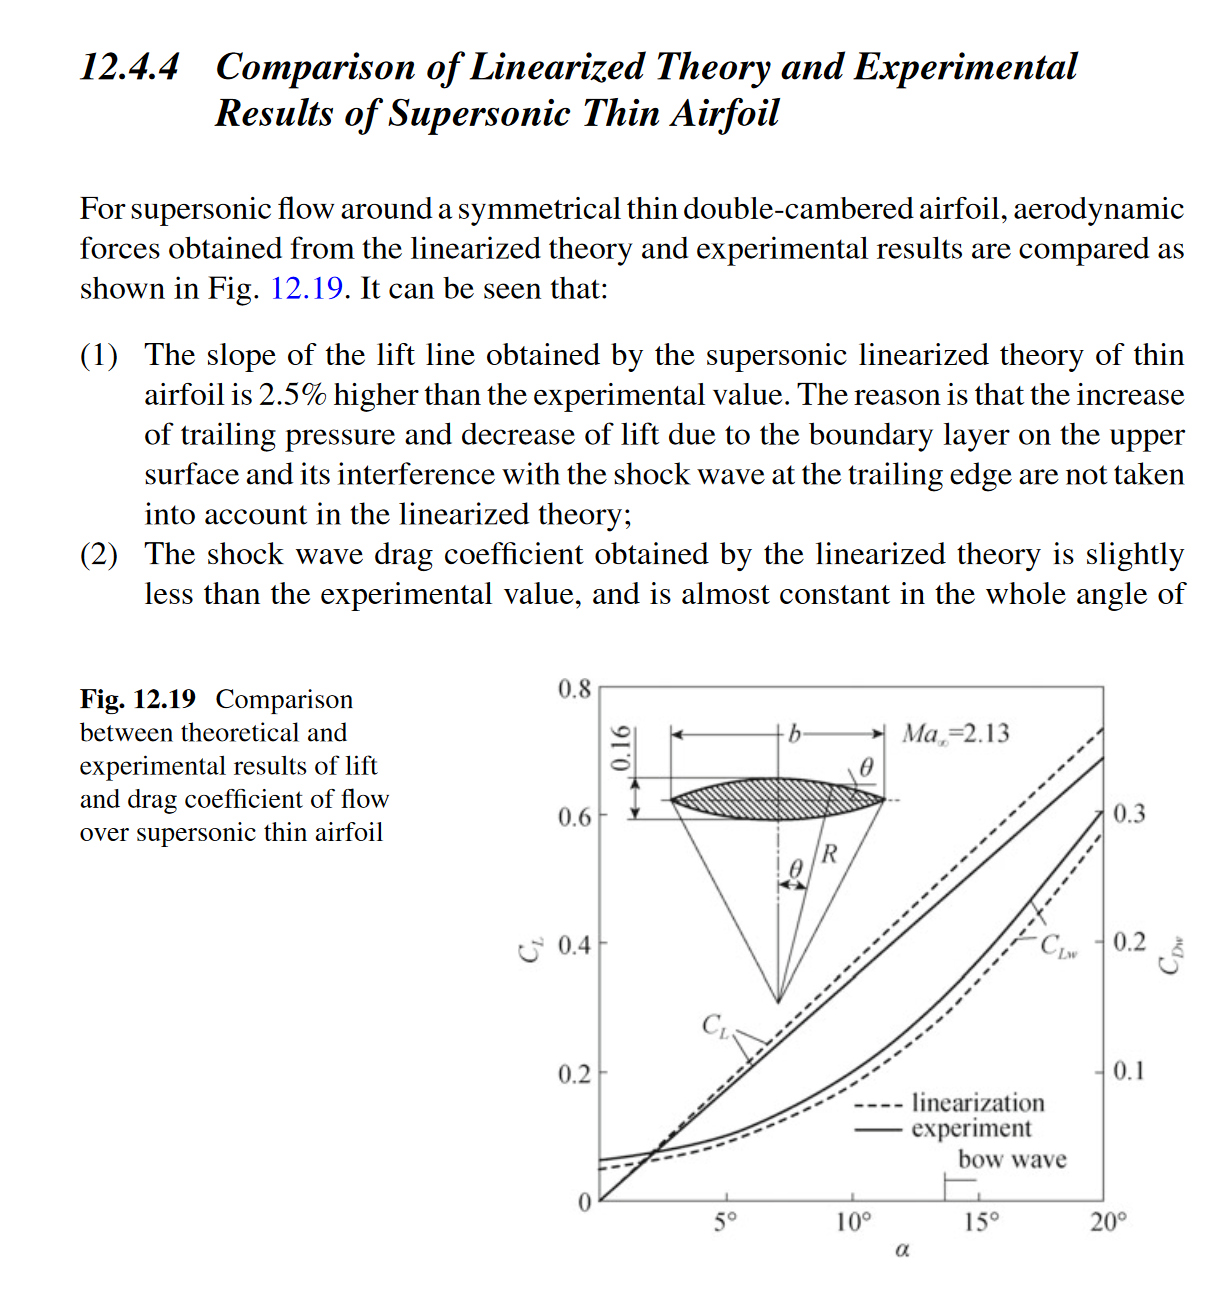

[P. Liu, Aerodynamics, [https://doi.org/10.1007/978-981-19-4586-1_12]](https://doi.org/10.1007/978-981-19-4586-1_12])